# Lesson I.3:   The Gauss-Jordan Elimination Algorithm:   Preliminaries (F24)

### Systems of linear equations and the augmented matrix representation

A ***system of ***$m$*** linear equations with ***$n$*** unknowns*** is a list of $m$ linear equations each having variables from a given finite set of variables such as$\{x_1,x_2,\dots,x_n\}
$:

            (I.3.1)                            $\left\{ \matrix{
a_{11}x_1&+&a_{12}x_2&+&\cdots &+&a_{1n}x_n &=& b_1 \cr
a_{21}x_1&+&a_{22}x_2&+&\cdots &+&a_{2n}x_n &=& b_2 \cr
\vdots&&\vdots&&\vdots &&\vdots&&\vdots \cr
a_{m1}x_1&+&a_{m2}x_2&+&\cdots &+&a_{mn}x_n &=& b_m \cr
}
\right.$

Here $m$ and $n$ are positive integers.    In high school algebra, $m$ and $n$ typically have the values of 2 or 3.    In some relatively common modern applications, however, these values are in the thousands or millions or more.   

As noted in the previous lesson, an important way of denoting a linear system is by its ***augmented matrix*** which is a rectangular array of numbers having $m$ rows and $n+1$ columns.   The augmented matrix for (I.3.1) is

           (I.3.2)                             $\left[\matrix{
a_{11} & a_{12} & \cdots & a_{1n} & b_1\cr
a_{21} & a_{22} & \cdots & a_{2n} & b_2\cr
\vdots & \vdots & \vdots & \vdots & \vdots \cr
a_{m1} & a_{m2} & \cdots & a_{mn} & b_m\cr
}
\right]$.

The $i$th column of the first $n$ columns of the augmented matrix contain the coefficients for the $i$th unknown in the various equations, and the ($n+1$)th column contains the constants on the right-hand side of the equal signs in (I.3.1).     

The augmented matrix has two components, the **coefficient matrix** and the **right-hand side** (**RHS**).   The coefficient matrix consists of the first $n$ columns of the augmented matrix and contains the coefficients of the unknowns of the problem.    The RHS is the last column of the augmented matrix.     

                    $\matrix{\text{coefficient}\cr\text{matrix}}\qquad\left[\matrix{
a_{11} & a_{12} & \cdots & a_{1n}\cr
a_{21} & a_{22} & \cdots & a_{2n} \cr
\vdots & \vdots & \vdots & \vdots  \cr
a_{m1} & a_{m2} & \cdots & a_{mn} \cr
}
\right]$             and            $\text{RHS}\qquad\left[\matrix{b_1\cr b_2 \cr \vdots\cr b_m}\right]$

The terminology "right-hand side" or RHS of course refers to an intermittently observed convention of writing the constant term of a linear equation on the right side of the equation.   Slightly less common but perhaps more mathematically descriptive nomenclature would be the ***constant term*** or ***inhomogeneous term*** of the linear system.   

The augmented matrix is our first example of a ***partitioned matrix ***which is a matrix created by pasting two or more matrices together to form a larger matrix.    The submatrices of a partitioned matrix are sometimes indicated with lines drawn through the matrix:

                                             
$$\left[\matrix{\matrix{
a_{11} & a_{12} & \cdots & a_{1n}\cr
a_{21} & a_{22} & \cdots & a_{2n} \cr
\vdots & \vdots & \vdots & \vdots  \cr
a_{m1} & a_{m2} & \cdots & a_{mn} \cr
} &\matrix{\big|\cr\bigg | \cr\bigg | \cr \bigg |}&\matrix{b_1\cr b_2\cr \vdots\cr b_m}
}
\right]$$


MATLAB provides tools for creating partitioned matrices and working with their submatrices.    Given the coefficient matrix and the RHS, the augmented matrix is constructed using concatenation:

A=[1 2 3; 4 5 6; 7 8 9]     % an example of a coefficient matrix

A =      1     2     3
     4     5     6
     7     8     9


b=[1;1;1]                   % an compatible example of a RHS

b =      1
     1
     1


G=[A b]                     % concatenation of two compatible matrices using square brackets

G =      1     2     3     1
     4     5     6     1
     7     8     9     1


MATLAB indexing allows extraction of the coefficient matrix and the RHS from the augmented matrix:

G(:,1:3)                 % extracting entries of all rows and columns 1 through 3 of G

ans =      1     2     3
     4     5     6
     7     8     9


G(:,4)                      % extracting the fourth column

ans =      1
     1
     1


### **Solutions of linear systems and equivalent linear systems**

A ***solution ***of a linear system is a set of values for the unknown variables that makes all the equations in the system true.    For the sake of convenience, we will arrange such values of the unknowns into a vector and call this vector a ***solution vector ***(or simply a solution) for the system.   For example, the linear system

     (I.3.3)           $\left\{\quad\matrix{
x_1 &+&2x_2&+&3x_3&=&1\cr
4x_1&+&5x_2&+&6x_3&=&1\cr
7x_1&+&8x_3&+&9x_3&=&1\cr}$      has         $\left[\matrix{x_1\cr x_2\cr x_3}\right]=\left[\matrix{-1\cr1\cr0}\right]$    and        $\left[\matrix{x_1\cr x_2 \cr x_3}\right]=\left[\matrix{0\cr-1\cr1}\right]$        as solution vectors.

The set of all solutions of a linear system is called the **solution set** of the linear system.    To solve a linear system is to identify all the solutions of the linear system, i.e., to find the solution set of the linear system.   As we have seen earlier, there are various possibilities for the number of solutions in the solution set.   The solution set may be empty, in which case the linear system is said to be ***inconsistent.***   The solution set may have exactly one element in which case the system is said to have a ***unique*** solution.    The solution set may have infinitely many solutions in which case the system is said to be ***dependent*** (at least by some authors).    As we will later see, the number of solutions in the solution set of a linear system of equations is always ***0,1 or ***${\bf\infty}$.   Determining the number of solutions in the solution set is an obviously necessary step towards solving the linear system.

That a solution set cannot consist of a finite number of solutions greater than 1 is a consequence of the solution set being an ***affine set****.   *A set of vectors is ***affine*** when it has the property that whenever two distinct points, say ${\bf x}$ and ${\bf y}$, are in the set then every point on the line through those two points is also in the set.   

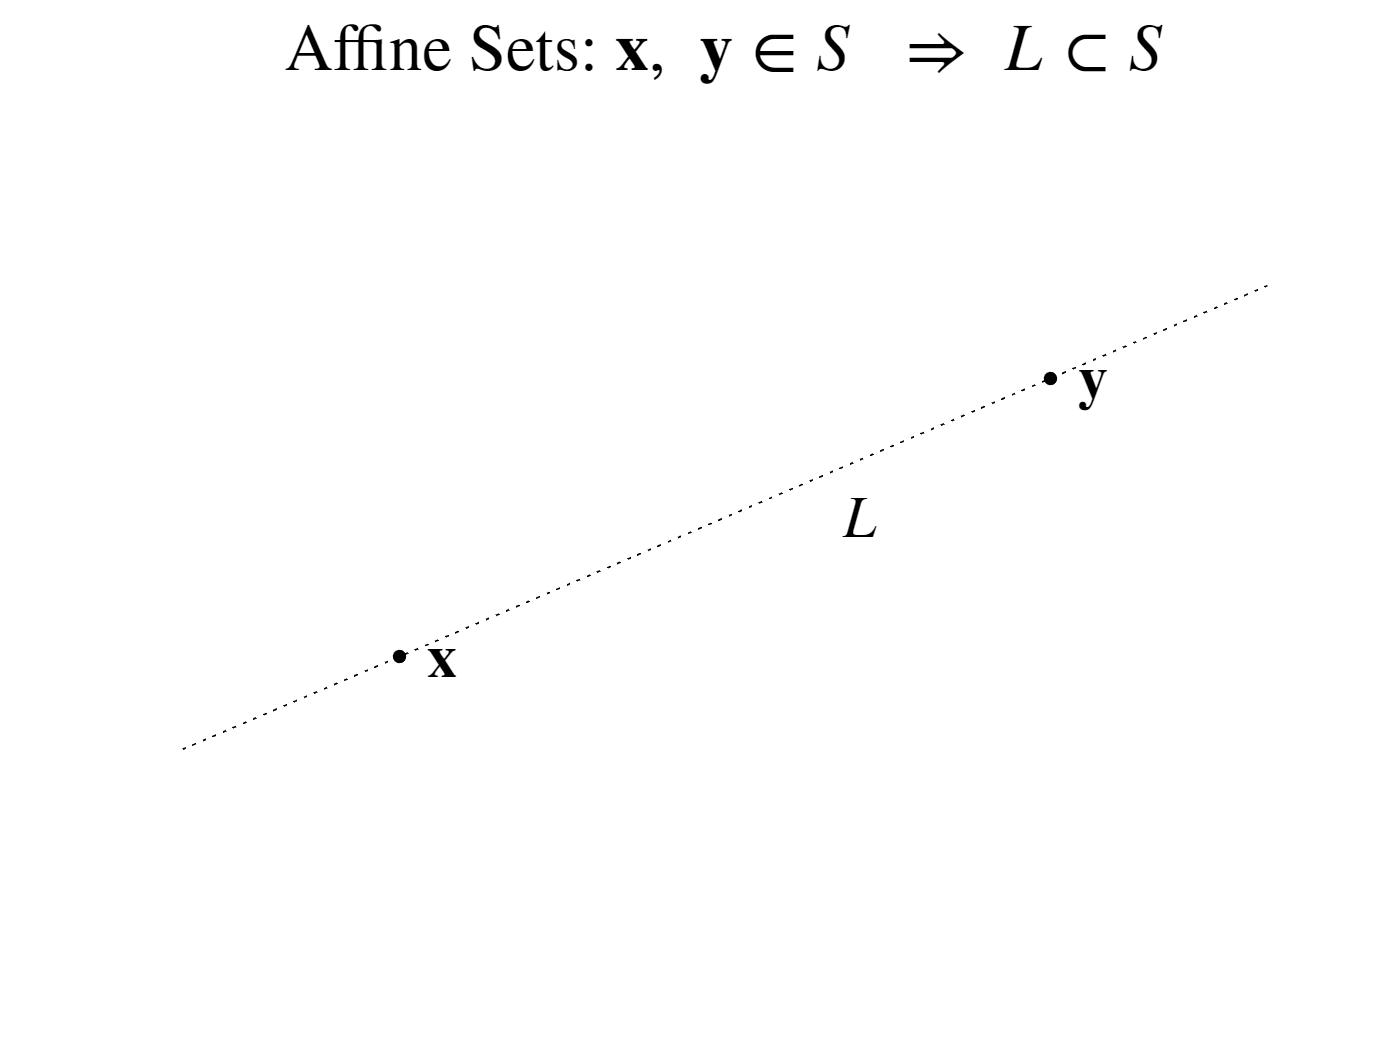

fig1()

When we later establish that the solution set is affine, this will show that if there is more than one vector in the solution set then there are necessarily infinitely many points in the solution set.    Algebraically, the line passing through ${\bf x}$ and ${\bf y}$ is the set of linear combinations of these vectors where the sum of the coefficients is 1:

            (I.3.4)                                                    $\text{line through }~{\bf x}~\text{ and}~ {\bf y}~=~\left\{\alpha{\bf x}+\beta{\bf y}~:~\alpha+\beta=1\right\}$

Linear combinations of a collection of vectors where the coefficients have a sum of 1 are known as ***affine combinations.*** 

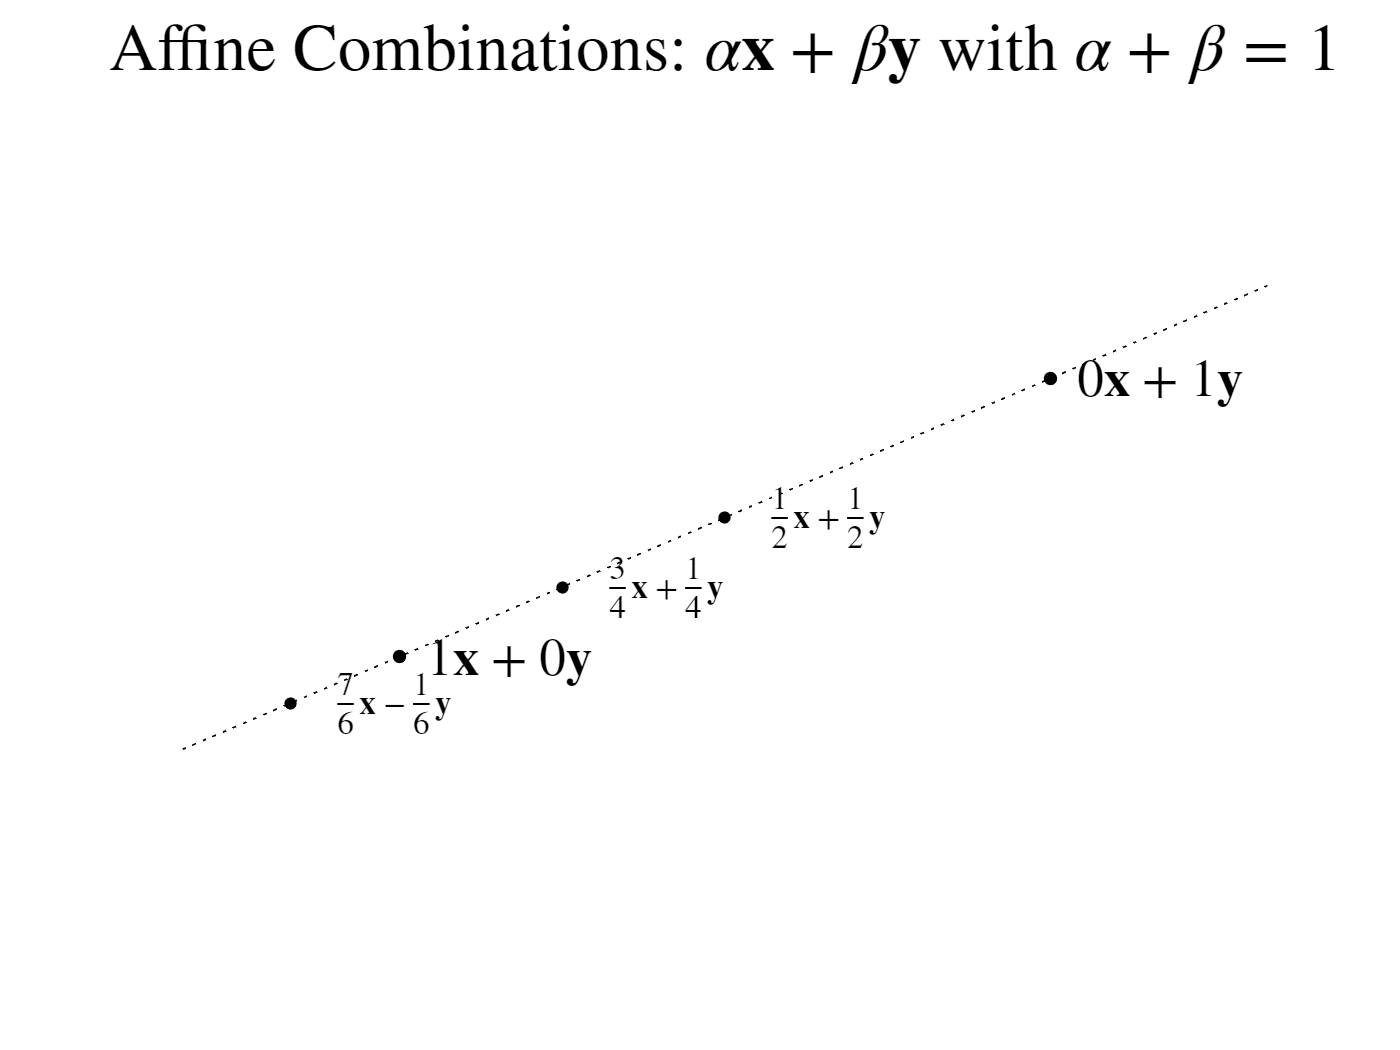

fig2()

When two linear systems share the same solution set, the two systems are said to be ***equivalent.***   The augmented matrices for equivalent linear systems are said to be equivalent as well.    If two matrices $A~\text{and}~B$ are equivalent, we write $A \sim B$.  

Our strategy for solving linear systems will be transforming the linear system to an equivalent system where the solution set is easily recognized.    The tool for executing this transformation will be elementary row operations.

### The elementary row operations

Elementary row operations act on augmented matrices to transform the augmented matrix into an equivalent augmented matrix.

Page 15 of the course textbook provides the definition of the three elementary row operations that can be performed on a matrix.

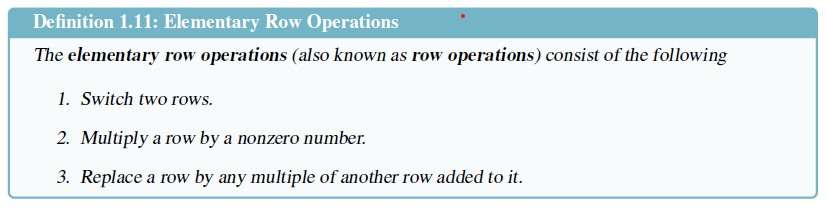

Students in Math 337 should expect to routinely perform these operations both by hand (pen & paper calculations) and using MATLAB throughout the course.   Here we discuss notations used to indicate these operations in both situations.

**Rows.    **The $\ell
$th row of an $m\times n$ matrix is itself a matrix of dimensions $1\times n$.    For example, the rows of


$$\qquad\qquad\qquad
A~=~ \left [ \matrix{
1 & 2 & 3 & 4 & 5 \cr
1 & 1 & 1 & 1 & 1 \cr
0 & 1 & 2 & 3 & 4 \cr}
\right ] \qquad
\text{are}
\qquad
{\bf r}_1 ~=~ \left [ \matrix{ 1 & 2 & 3 & 4 & 5}\right],
\quad
{\bf r}_2 ~=~ \left [ \matrix{ 1 & 1 & 1 & 1 & 1}\right],
\quad\text{and}\quad
{\bf r}_3 ~=~ \left [ \matrix{ 0 &1 & 2 & 3 & 4 }\right].$$


Note:   Matrices with a single row are often called *row vectors****.***

MATLAB provides a convenient method for referring to a row of a matrix.    If A designates a matrix

A=[1 2 3 4 5; 1 1 1 1 1; 0 1 2 3 4]

A =      1     2     3     4     5
     1     1     1     1     1
     0     1     2     3     4


then using a colon (:) as the column index will extract the row indicated by the row index.

r1 = A(1,:)

r1 =      1     2     3     4     5


r2 = A(2,:)

r2 =      1     1     1     1     1


r3 = A(3,:)

r3 =      0     1     2     3     4


This notational device makes working with entire rows relatively straightforward in MATLAB.

**Switch by hand.    **The first elementary row operation, ***switch*** (aka ***swap*** or ***exchange***), consists of exchanging two rows of a matrix.    For example, we form the matrix $B$ by exchanging the second and third rows of the matrix $A\ldotp$


$$\qquad\qquad\qquad\qquad
B~=~ \left [ \matrix{
1 & 2 & 3 & 4 & 5 \cr
0 & 1 & 2 & 3 & 4 \cr
1  & 1 & 1 & 1 & 1 \cr
}\right ]$$


That is, the result of elementary row operation of switching the second and third rows of $A$ is $B$.

When calculating on paper, we will often use an up arrow ($\uparrow$) and a down arrow ($\downarrow$) to indicate which rows are being swapped.


$$\qquad\qquad\qquad\qquad
\matrix{ \  \cr \downarrow \cr \uparrow}~
\left [ \matrix{
1 & 2 & 3 & 4 & 5 \cr
1 & 1 & 1 & 1 & 1 \cr
0 & 1 & 2 & 3 & 4 \cr}
\right ] \quad{\tilde}\quad
\left [ \matrix{
1 & 2 & 3 & 4 & 5 \cr
0 & 1 & 2 & 3 & 4 \cr
1 & 1 & 1 & 1 & 1 \cr
}
\right ] $$
 

The arrows indicate that the second matrix (a matrix equivalent to the first) is derived from the first by a switch operation on the second and third rows.    

**Switch with MATLAB.**  The technique we will use to swap rows `p` and `q` in MATLAB in place is to (1) copy row `p` to a temporary location, (2) overwrite row `p` with row `q`, (3) copy the original values of row `q` from the temporary location to row `q`.   Note:   "in place" means that we are using the original name for the matrix for the result of the operation (i.e. the matrix is "changing").    

temp = A(2,:)        % copy second row to temporary location

temp =      1     1     1     1     1


A(2,:) = A(3,:)      % copy thrid row to second row

A =      1     2     3     4     5
     0     1     2     3     4
     0     1     2     3     4


A(3,:) = temp        % copy stored values of the second row to the third row

A =      1     2     3     4     5
     0     1     2     3     4
     1     1     1     1     1


In MATLAB there is a technique using just one line to accomplish the exchange operation (without explicit temporary storage).    It is not necessary to use this method in this course, but we present it (without further explanation) so that the interested reader is aware.

A([3 2],:) = A([2 3],:)

A =      1     2     3     4     5
     1     1     1     1     1
     0     1     2     3     4


(This second exchange has restored the entries of `A` to their original locations.)

Alternatively, we can implement a MATLAB function (which we will call `SWAP) `to perform the switch operation.

`    function ``A = SWAP(A,p,q)`

`    %  Exchanges row p and row q of the matrix A`

`        temp_row = A(p,:);`

`        A(p,:) = A(q,:);`

`        A(q,:) = temp_row;`

`    end`

SWAP(A,1,3)    % ouput the result of swapping the first and third row of A (N.B.  A is unchanged)

ans =      0     1     2     3     4
     1     1     1     1     1
     1     2     3     4     5


A

A =      1     2     3     4     5
     1     1     1     1     1
     0     1     2     3     4


**Multiply a row by hand.**   The second elementary row operation, **multiplying a row by a nonzero number** (aka **scaling** the row) consists of multiplying each entry of a row by a nonzero number.     For example, if we multiply the third row of the matrix $A$ by -3 we obtain 

$\qquad\qquad\qquad\qquad
C~=~  \left [ \matrix{
1 & 2 & 3 & 4 & 5 \cr
1 & 1 & 1 & 1 & 1 \cr
0 & -3 & -6 & -9 & -12 \cr}
\right ] $.

That is, $C$ is the result of multiplying the third row of $A$ by -3.

When calculating on paper, we will often indicate the row operation by placing a times sign ($\times$) and the nonzero multiplier before the row being scaled.


$$\qquad\qquad\qquad\qquad
\matrix{ \  \cr \ \cr \times-3}~
\left [ \matrix{
1 & 2 & 3 & 4 & 5 \cr
1 & 1 & 1 & 1 & 1 \cr
0 & 1 & 2 & 3 & 4 \cr}
\right ] \quad{\tilde}\quad
\left [ \matrix{
1 & 2 & 3 & 4 & 5 \cr
1 & 1 & 1 & 1 & 1 \cr
0 & -3 & -6 & -9 & -12 \cr}

\right ] $$


We note that multiplying by zero is disallowed as a row operation as this operation fails to be reversible, i.e., the original matrix would not be restored by dividing by the multiplier.   We also note that multiple operations can (legitimately) be indicated with this notation.


$$\qquad\qquad\qquad\qquad
\matrix{ \times 2  \cr \times 7 \cr \times-3}~
\left [ \matrix{
1 & 2 & 3 & 4 & 5 \cr
1 & 1 & 1 & 1 & 1 \cr
0 & 1 & 2 & 3 & 4 \cr}
\right ] \quad{\tilde}\quad
\left [ \matrix{
2 & 4 & 6 & 8 & 10 \cr
7 & 7 & 7 & 7 & 7 \cr
0 & -3 & -6 & -9 & -12 \cr}

\right ] $$


**Multiply a row with MATLAB.  **Scaling a row, in place, is very easy to perform in MATLAB.

A(3,:)=-3*A(3,:)

A =      1     2     3     4     5
     1     1     1     1     1
     0    -3    -6    -9   -12


A MATLAB function, SCALE, to return the input matrix with the $p^\text{th}$ row multiplied by `multiplier` is easily written:

`    function ``A = SCALE(A,p,multiplier)`

`    %   Multiplies row p by multiplier`

`        A(p,:) = multiplier*A(p,:);`

`    end`

A = SCALE(A,3,-1/3)

A =      1     2     3     4     5
     1     1     1     1     1
     0     1     2     3     4


The earlier scaling has been reversed to obtain the original matrix `A`.   Note that this code "trusts" the user not to enter 0 as a multiplier.

**Replace by hand.   **The third elementary row operation, **replace** (aka **add multiple to** or **subtract multiple from) **consists of replacing a row of the matrix with that row plus (or minus) a multiple of another row.   Here we use the description of the operation as subtracting a multiple of one row from another; this seems to align well with the notion of elimination discussed below.     For example, we create the matrix $D$ by subtracting 3 times the third row of $A$ from the first row.


$$\qquad\qquad\qquad
D~=~ \left [ \matrix{
1 & -1 & -3 & -5 & -7 \cr
1 & 1 & 1 & 1 & 1 \cr
0 & 1 & 2 & 3 & 4 \cr}
\right ] $$


When calculating on paper, we use a dot ($\bullet$) to indicate the row used to form the multiple and the numerical value is placed next to the row from which the multiple is being subtracted.


$$\qquad\qquad\qquad\qquad
\matrix{ 3  \cr \ \cr \bullet}~
\left [ \matrix{
1 & 2 & 3 & 4 & 5 \cr
1 & 1 & 1 & 1 & 1 \cr
0 & 1 & 2 & 3 & 4 \cr}
\right ] \quad{\tilde}\quad
 \left [ \matrix{
1 & -1 & -3 & -5 & -7 \cr
1 & 1 & 1 & 1 & 1 \cr
0 & 1 & 2 & 3 & 4 \cr}
\right ] $$


Note that we can use this notation legitimately to indicate subtraction of different multiples of the same row from more than one row.   For example, we subtract 2 times the second row of $A$ from the first row and 1 times the second row from the third row:


$$\qquad\qquad\qquad\qquad
\matrix{ 2  \cr \bullet \cr 1}~
\left [ \matrix{
1 & 2 & 3 & 4 & 5 \cr
1 & 1 & 1 & 1 & 1 \cr
0 & 1 & 2 & 3 & 4 \cr}
\right ] \quad{\tilde}\quad
 \left [ \matrix{
-1 & 0 & 1 & 2 & 3 \cr
1 & 1 & 1 & 1 & 1 \cr
-1 & 0 & 1 & 2 & 3 \cr}
\right ] $$


**Replace with MATLAB.**    Using the colon (`:`) for the MATLAB index makes subtracting a multiple of one row from another very easy.    For example, we can compute, in place, the result of subtracting 3 times the third row of $A$ from the first row as follows:

A(1,:) = A(1,:) - 3*A(3,:)

A =      1    -1    -3    -5    -7
     1     1     1     1     1
     0     1     2     3     4


Note that the assignment operator (`=`) changes $A\ldotp$    We can restore the original values for $A$ by performing the inverse operation:

A(1,:) = A(1,:) - (-3)*A(3,:)

A =      1     2     3     4     5
     1     1     1     1     1
     0     1     2     3     4


Because the primary use of the row operation replace is to implement elimination (see next section) we prefer to think of it as subtracting a multiple of one row from another.   This point-of-view motivates the naming of the MATLAB function `SUB`.  

    function A = SUB(A,p,multiplier,q)

    %  Row q is replaced by row q minus multiplier times row p

        A(q,:) = A(q,:) - multiplier*A(p,:);

    end

SUB(A,3,1/4,2)

ans =     1.0000    2.0000    3.0000    4.0000    5.0000
    1.0000    0.7500    0.5000    0.2500         0
         0    1.0000    2.0000    3.0000    4.0000


**The elimination step.    **In the approach to solving linear systems pursued here, the primary technique is to use replacement operations to obtain an equivalent system with a large number of (carefully arranged) zeros for entries in the augmented matrix.   The replacement operations used each have the effect of setting a particular entry of the matrix to zero.    Here we call a replacement operation designed with the purpose to set a particular entry in a matrix to zero an ***elimination step****.  *

Given an augmented matrix of a linear system, suppose that we seek to find an equivalent system having a particular coefficient $a_{ij}$ equal to zero.    To obtain this system having zero in the $i^\text{th}$ row and $j^\text{th}$ column, we make particular use of an entry in $\ell^\text{th}$ row ($i\ne\ell
$) of the $j^\text{th}$ column.   The one essential requirement of $a_{\ell j}
$ is that it is nonzero (because division by this value is required).     The manner in which this elimination step is implemented is to subtract the $\ell^\text{th}$ row multiplied by $\frac{a_{i j}}{a_{\ell j}}$ from the $i^\text{th}$ row (third type of row operation).

        
$$\matrix{
~\cr~\cr\bullet\cr~\cr a_{ij}/a_{\ell j}\cr~\cr~\cr
}
\left[
\matrix{
a_{11} & \cdots & a_{1j} & \cdots & a_{1n} & a_{1n+1} \cr
\vdots  & & \vdots & & \vdots & \vdots \cr
a_{\ell 1} & \cdots & a_{\ell j} & \cdots & a_{\ell n} & a_{\ell n+1} \cr
\vdots  & & \vdots & & \vdots & \vdots \cr
a_{i 1} & \cdots & a_{i j} & \cdots & a_{i n} & a_{i n+1} \cr
\vdots  & & \vdots & & \vdots & \vdots \cr
a_{m 1} & \cdots & a_{m j} & \cdots & a_{m n} & a_{m n+1} \cr} \right] \quad\sim\quad
$$


        
$$\left[
\matrix{
a_{11} & \cdots & a_{1j} & \cdots & a_{1n} & a_{1n+1} \cr
\vdots  & & \vdots & & \vdots & \vdots \cr
a_{\ell 1} & \cdots & a_{\ell j} & \cdots & a_{\ell n} & a_{\ell n+1} \cr
\vdots  & & \vdots & & \vdots & \vdots \cr
a_{i 1}-a_{\ell 1}\frac{a_{ij}}{a_{\ell j} & \cdots & a_{i j}-a_{\ell j} \frac{a_{ij}}{a_{\ell j} & \cdots & a_{i n}-a_{\ell j} \frac{a_{ij}}{a_{\ell n} & a_{i n+1}-a_{\ell n+1} \frac{a_{ij}}{a_{\ell j} \cr
\vdots  & & \vdots & & \vdots & \vdots \cr
a_{m 1} & \cdots & a_{m j} & \cdots & a_{m n} & a_{m n+1} \cr} \right] {\quad=\quad}
\left[
\matrix{
a_{11} & \cdots & a_{1j} & \cdots & a_{1n} & a_{1n+1} \cr
\vdots  & & \vdots & & \vdots & \vdots \cr
a_{\ell 1} & \cdots & a_{\ell j} & \cdots & a_{\ell n} & a_{\ell n+1} \cr
\vdots  & & \vdots & & \vdots & \vdots \cr
a_{i 1}-a_{\ell 1}\frac{a_{ij}}{a_{\ell j} & \cdots & 0 & \cdots & a_{i n}-a_{\ell j} \frac{a_{ij}}{a_{\ell n} & a_{i n+1}-a_{\ell n+1} \frac{a_{ij}}{a_{\ell j} \cr
\vdots  & & \vdots & & \vdots & \vdots \cr
a_{m 1} & \cdots & a_{m j} & \cdots & a_{m n} & a_{m n+1} \cr~\cr} \right]$$


Implementing elimination steps in MATLAB is straightforward.   Here the $j^\text{th}$ element of the $\ell^\text{th}$ row is used to eliminate the $j^\text{th}$ element of the $i^\text{th}$ row. 

i=2;
j=1;
l=1;
mult = A(i,j)/A(l,j);    % ratio of the term to be eliminated to the term used to eliminate it
SUB(A,l,mult,i)

ans =      1     2     3     4     5
     0    -1    -2    -3    -4
     0     1     2     3     4


#### Reversibility and equivalence

If an augmented matrix $B$ is derived from an augmented matrix $A$ by an elementary row operation why are the solutions sets of the linear systems represented by $A$ and $B$ the same?    If ${\bf x}=(x_1,x_2,\dots,x_n)$ is a solution for the linear system represented by$A$ then it is evident that that $\bf x$ is also a solution for the linear system represented by $B$ because the row operation used to obtain $B$ preserve equality in each equation of the system.   For example,

                
$$\left\{ \matrix{1 x &+&2y&+&3z&=&1 \cr 4x&+&5y&+&6z &=& 1}\right.\qquad\Rightarrow\qquad
\left\{ \matrix{1 x &+&2y&+&3z&=&1 \cr &-&3y&-&6z &=& -3}\right.
$$


because the first equation times -4 has been added to the second equation corresponding to a particular replacement operation.    What is less obvious is that all the solutions of the second system are also solutions of the first system.   The way to see that this is the case is to recognize that there is an elementary row operation that will transform the system represented by $B$ back to the system represented by $A$.   In the example above, we simply add 4 times the first row (equation) to the second row (equation).     Because each row operation can be reversed by another row operation, we say that row operations are ***reversible.***   The reversibility of elementary row operations is key to our development of linear algebra.

**Examples of row operations and the row operations reversing them**


$$\matrix{\downarrow\cr\uparrow}
\left[\matrix{1 & 2 & 3\cr 4 &5 & 6}\right]~\sim~
\matrix{\downarrow\cr\uparrow}
\left[\matrix{ 4 &5 & 6\cr1 & 2 & 3}\right]~\sim~
\left[\matrix{1 & 2 & 3\cr 4 &5 & 6}\right]$$



$$\matrix{~\cr\times7}
\left[\matrix{1 & 2 & 3\cr 4 &5 & 6}\right]~\sim~
\matrix{ ~\cr\times\frac17}
\left[\matrix{ 1 & 2 & 3\cr 28 &35 & 42}\right]~\sim~
\left[\matrix{1 & 2 & 3\cr 4 &5 & 6}\right]$$



$$\matrix{\bullet\cr2}
\left[\matrix{1 & 2 & 3\cr 4 &5 & 6}\right]~\sim~
\matrix{\bullet\cr-2}
\left[\matrix{ 1 &2 & 3\cr2&1&0}\right]~\sim~
\left[\matrix{1 & 2 & 3\cr 4 &5 & 6}\right]$$


The need for reversibility explains why certain operations that might appear to be elementary row operations are excluded from that category.   Most importantly, scaling by zero (multiplying a row by zero) is not an elementary row operation because the operation can not be reversed as scaling is reversed by division by the multiplier.    Indeed, scaling by zero will generally enlarge the solution set:

        The solution set of  $\left\{\matrix{ x&-&y&=&0\cr
x&+&y&=&2}\right.
$  is the single point  $\left[\matrix{x\cr y}\right]=\left[\matrix{1\cr1}\right]$but "scaling" the second equation by zero gives 

        the linear system  $\left\{\matrix{ x&-&y&=&0\cr
&&0&=&0}\right.
$  which has infinitely many solutions namely $\left[\matrix{x\cr y }\right] = \left[\matrix{s \cr s} \right]$ where $s$ is any number.

Note that because adding a multiple of a row to itself is equivalent to scaling the row, we exclude this operation (adding -1 times a row to itself is equivalent to scaling the row by zero).     

#### **Row-echelon forms**     

The goal of the Gauss-Jordan algorithm is to find an equivalent matrix having a structure known as the ***reduced row-echelon form***.   In the process, important intermediate row-echelon forms having both theoretical and practical significance are encountered.     These matrices are identified by the locations of the ***leading entries*** of the rows of the matrix.   The leading entry of a row is the first nonzero element of the row (if any).    For example, the matrix $A=\left[\matrix{3 & 4 & 2 & 3  & 0\cr 0 & 3 & 0 & 2 & 1 \cr 0 & 0 & 0 & 0 & 0 \cr 0 & 0 & 1 & 2 & 3}\right]$ has leading entries in the first column of the first row, in the second column of the second row and in the third column of the fourth row.   The third row of $A$, being a row of zeros, has no leading element.    With this concept, the various row-echelon forms may be defined.

A matrix is in ***proto-row-echelon form*** if and only if 

    (a)  All nonzero rows are above any rows of zeros.

    (b)  The leading entry of every nonzero row is to the right of the leading entries of the rows above it.

Examples of matrices in proto-row-echelon form include

                $\left[\matrix{1 & 2 & 3 & 4 \cr 0 & 2 & 3 & 4 \cr 0 & 0 & 3 & 4 \cr 0 & 0 & 0 & 4}\right],\qquad
\left[\matrix{0&0&0\cr0&0&0\cr0&0&0\cr0&0&0\cr0&0&0\cr0&0&0}\right],\qquad \left[\matrix{0 & 0 & 7 & 8 & \pi\cr 0 & 0 & 0 &\sqrt{2} & \frac{22}{7}\cr 0 & 0 &0 &0 & 0}\right],\qquad\left[\matrix{1 & 2 & 1 & 3 & 0 & 0 & 2 &0 & 1\cr 0 & 0 & 4 & 3 & 0 & 0 &0& 1 & 2  \cr
0 & 0 & 0 & 0 & 0 & 3 & 0 & 0 &0 \cr
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 }\right]$.

The importance of the proto-row-echelon form is that the number and locations of the leading entries can be identified by inspection.   While there are typically many proto-row-echelon form matrices equivalent to a given matrix, they will all share the number and locations of the leading entries.    The positions of the leading entries of an equivalent proto-row echelon matrix are known as the ***pivot locations*** of the matrix.

A matrix is in ***normalized row-echelon form ***if and only if the matrix is in proto-row-echelon form and

    (c)  Any leading entry of a row equals one.

Examples of matrices in normalized row-echelon form include

                $\left[\matrix{
1 & 2 & 3 & 4 \cr 
0 & 1 & \frac32 & 2 \cr 
0 & 0 & 1 & \frac43 \cr 0 & 0 & 0 & 1}\right],\qquad
\left[\matrix{0&0&0\cr0&0&0\cr0&0&0\cr0&0&0\cr0&0&0\cr0&0&0}\right],\qquad \left[\matrix{
0 & 0 & 1 & \frac87 & \frac{\pi}7\cr 
0 & 0 & 0 &1 & \frac{22\sqrt{2}}{7}\cr 
0 & 0 &0 &0 & 0
}\right],\qquad\left[\matrix{1 & 2 & 1 & 3 & 0 & 0 & 2 &0 & 1\cr 0 & 0 & 1 & 3 & 0 & 0 &0& 1 & 2  \cr
0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 &0 \cr
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 }\right]$.

Note that the requirements of a proto-row-echelon form guarantee that the entries below any pivot location are zero.   

A matrix is in ***reduced row-echelon form (rref) ***if and only if the matrix is in normalized row-echelon form and

    (d)  The entries above any leading entries in the matrix are zero.

Examples of matrices in reduced row-echelon form include

                $\left[\matrix{
1 & 0 & 0 & 0 \cr 
0 & 1 & 0 & 0 \cr 
0 & 0 & 1 & 0 \cr 0 & 0 & 0 & 1}\right],\qquad
\left[\matrix{0&0&0\cr0&0&0\cr0&0&0\cr0&0&0\cr0&0&0\cr0&0&0}\right],\qquad \left[\matrix{
0 & 0 & 1 & 0          & \frac{\pi}7\cr 
0 & 0 & 0 &1           & \frac{22\sqrt{2}}{7}\cr 
0 & 0 &0 &0 & 0
}\right],\qquad\left[\matrix{
1 & 2 & 0 & 3 & 0 & 0 & 2 &0 & 1\cr 
0 & 0 & 1 & 3 & 0 & 0 &0& 1 & 2  \cr
0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 &0 \cr
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 }\right]$.

**A preliminary observation regarding rref.**    To gain some insight into some of the purposes for studying the reduced row-echelon form consider the example

            $G_1=\left[\matrix{1&2&3&1\cr 4&5&6&1\cr 7&8&10&1}\right]$    which is the augmented matrix for the linear system    $\left\{\matrix{
x_1 &+&2x_2&+&3x_3 &=&1\cr
4x_1 &+&5x_2&+&6x_3 &=&1\cr
7x_1 &+&8x_2&+&10x_3 &=&1\cr}\right.$.

Superficial observation does not easily reveal the solution set or even how many solutions there might be.    The equivalent rref matrix is

            $\text{rref}(G_1)=\left[\matrix{1&0&0&-1\cr 0&1&0&1\cr 0&0&1&0}\right]$    which is the augmented matrix for the linear system    $\left\{\matrix{
x_1 &&&& &=&-1\cr
&&x_2&& &=&1\cr
&&&&x_3 &=&0\cr}\right.$.  

For this system it is evident that there is one solution, and that the unique solution vector is ${\bf x}=\left[\matrix{-1\cr 1\cr 0}\right]$.

The basic idea is that when the augmented matrix is rref it is possible to solve each equation for its leading variable (called a ***basic variable*** of the system) and that that leading variable appears in no other equation.    In the above example, this allows us to solve for all the unknowns of the system (making the solution unique).    Systems having more than one solution are somewhat more complex, but the same general idea holds.    For example, consider

            $G_2=\left[\matrix{1&2&3&1\cr 4&5&6&1\cr 7&8&9&1}\right]$    which is the augmented matrix for the linear system    $\left\{\matrix{
x_1 &+&2x_2&+&3x_3 &=&1\cr
4x_1 &+&5x_2&+&6x_3 &=&1\cr
7x_1 &+&8x_2&+&9x_3 &=&1\cr}\right.$.

Superficial observation does not easily reveal the solution set or even how many solutions there might be.    The equivalent rref matrix is

            $\text{rref}(G_2)=\left[\matrix{1&0&-1&-1\cr 0&1&2&1\cr 0&0&0&0}\right]$    which is the augmented matrix for the linear system                        

                                                                $\left\{\matrix{
x_1 &&&-&x_3 &=&-1\cr
&&x_2&+&2x_3 &=&1\cr
&&&& 0&=&0\cr}\right.$.  

We can solve the first equation for $x_1$ and the second equation for $x_2$ but each of these basic variables will depend on $x_3$. 

                                                                
$$\left\{\matrix{
x_1 &=&-1&+&x_3\cr
x_2&=&1&-&2x_3 \cr
 0&=&0\cr}\right.$$


The crucial observation is that we may choose any value we like for $x_3$ which then defines values for $x_1$ and $x_2$ giving a solution of the linear system.    That is, there are infinitely many solutions parameterized by $x_3$.    These matters will be fully treated later but are considered here as motivation for the Gauss-Jordan algorithm.

### **Follow-up (aka homework)**

**Problem I.3.1:**     Consider the linear system $\left\{ 
\matrix{
3x_1&+&5x_2&+&3x_3&=&1\cr
&&9x_2&+&8x_3&=&4\cr
}$.

What is the augmented matrix for this system?   The coefficient matrix?   The RHS?

**Problem I.3.2:**     Consider the linear system having the augmented matrix $\left[\matrix{0 & 1 & 0 & 4 & 2\cr 0 & 0 & 1 &3 & 7\cr 0 & 0 & 0 & 0 & 0}\right]$.   How many equations are there in this system?    How many unknowns are there in this system.  What is the coefficient matrix of the system?   The RHS of the system?

Which of the following vectors are in the solution set of this system?

                                                       $\left[\matrix{0\cr 0 \cr 0 \cr0}\right],\qquad
\left[\matrix{0\cr 2 \cr 7 \cr0}\right],\qquad
\left[\matrix{\pi \cr 2 \cr 7 \cr0}\right],\qquad
\left[\matrix{3+4i\cr 2 \cr 7 \cr0}\right],\qquad
\left[\matrix{0\cr -2 \cr 4 \cr1}\right],\qquad
\left[\matrix{\sqrt{2}\cr e^{\pi i/4} \cr 22/7 \cr 19}\right]$.

**Problem I.3.3:**   What is the output from the following MATLAB commands?

    A=[1 2 3; 4 5 6; 7 8 9]

    B=[1 1 1 2; 1 1 1 3; 1 1 1 4]

    [A B]

    [A A]

    [A B A B]

    [A; A]

    [B; B]

    [A B; B A]

    [A; B]

**Problem I.3.4:   **Verify the two solutions given for the linear system (I.3.3).    Also verify that every affine combination of these two solutions is also a solution.

**Problem I.3.5:**   Compute the result of the indicated row operations.

            (a)    $\matrix{\downarrow\cr \cr \uparrow} \left[\matrix{1 & 2 & 3 \cr 4& 5 & 6 \cr 7 & 8 & 9}\right]$            (b)    $\matrix{\times 1\cr\times1/4 \cr \times1/7} \left[\matrix{1 & 2 & 3 \cr 4& 5 & 6 \cr 7 & 8 & 9}\right]$        (c)    $\matrix{\cdot\cr 4 \cr 7} \left[\matrix{1 & 2 & 3 \cr 4& 5 & 6 \cr 7 & 8 & 9}\right]$

**Problem I.3.6:**    What are the three row operations that could be used to eliminate $a_{13}$ from the matrix $A=\left[\matrix{1&2&3&4\cr 5 & 6 & 7 & 8 \cr 9 & 10 & 11 & 12\cr 13& 14 & 15 & 16}\right]$?   What is the result of each of those three row operations?

**Problem I.3.7:   **How many row operations are there that could be used to eliminate $a_{33}$ from the matrix $A=\left[\matrix{1&0 & 1 & 0 \cr 0 & 2 & 0 & 2 \cr 1 & 0 & 3 & 0}\right]$?   What is the result of  each of those row operations?

**Problem I.3.8:**   How many row operations are there that could be used to eliminate $a_{33}$ from the matrix $A=\left[\matrix{1&0 & 0 & 1 \cr 0 & 2 & 0 & 2 \cr 1 & 0 & 3 & 0}\right]$?   What is the result of each of those row operations?

**Problem I.3.9:   **What is the result of the following MATLAB commands:

    A=[1 2 3; 4 5 6; 7 8 9]

    A=SUB(A,1,4.0,2)

    A=SUB(A,1,7.0,3)

**Problem I.3.10:**  For the row operations notated and computed below, determine and notate the row operation that reverses the given operation.    In each case, is the solution unique?


$$\quad\text{(a)}\quad 
\matrix{~\cr\downarrow\cr~\cr \uparrow}\left[
\matrix{1&2&3\cr4&5&6\cr7&8&9\cr10&11&12}\right]~\sim~
\left[
\matrix{1&2&3\cr10&11&12\cr7&8&9\cr4&5&6\cr}\right]\qquad\qquad\qquad
\quad\text{(b)}\quad 
\matrix{~\cr~\cr\downarrow\cr \uparrow}\left[
\matrix{1&2&3\cr4&5&6\cr7&8&9\cr7&8&9}\right]~\sim~
\left[
\matrix{1&2&3\cr4&5&6\cr7&8&9\cr7&8&9}\right]$$



$$\quad\text{(c)}\quad 
\matrix{\times2~\cr~\cr~\cr ~}\left[
\matrix{1&2&3\cr4&5&6\cr7&8&9\cr10&11&12}\right]~\sim~
\left[
\matrix{2&4&6\cr4&5&6\cr7&8&9\cr10&11&12}\right]\qquad\qquad\qquad
\quad\text{(d)}\quad 
\matrix{\times2~\cr~\cr~\cr ~}\left[
\matrix{1&1&1\cr2&2&2\cr3&3&3\cr4&4&4}\right]~\sim~
\left[
\matrix{2&2&2\cr2&2&2\cr3&3&3\cr4&4&4}\right]$$



$$\quad\text{(e)}\quad 
\matrix{~\cr\bullet~\cr~\cr2~}\left[
\matrix{1&2&3\cr4&5&6\cr7&8&9\cr10&11&12}\right]~\sim~
\left[
\matrix{1&2&3\cr4&5&6\cr7&8&9\cr2&1&0}\right]\qquad\qquad\qquad
\quad\text{(f)}\quad 
\matrix{1/4~\cr~\cr~\cr \bullet~}\left[
\matrix{1&1&1\cr2&2&2\cr3&3&3\cr4&4&4}\right]~\sim~
\left[
\matrix{0&0&0\cr2&2&2\cr3&3&3\cr4&4&4}\right]$$


**Problem I.3.11*:  **Two matrices are said to be equivalent if as augmented matrices they represent linear systems having the same (nonempty) solution set.    (This condition is essentially the same as the existence of a sequence of row operations for converting one of the matrices to the other).    The notation for equivalent matrices is the tilde ($\tilde$) which is commonly used (perhaps overused) for all sorts of equivalence relations.    An equivalence relations is a mathematical relationship with three properties:

- Reflexivity:   $A\sim A$

- Symmetry:  $A\sim B\quad\Rightarrow B\sim A$.

- Transitivity:   $A\sim B~\text{and}~B\sim C\quad\Rightarrow\quad
A\sim C$.

Verify that equivalence between matrices as defined in this lesson has the three properties of an equivalence relation.

**Problem I.3.12:**   Demonstrate that the two matrices below are not equivalent.


$$\left[\matrix{1 & 2 & 3 &0\cr 4 & 5 & 6 & 0 \cr 7 &8&10&0}\right]\qquad\text{and}\qquad
\left[\matrix{1 & 2 & 3 &0\cr 4 & 5 & 6 & 0 \cr 0 &0&0&0}\right]$$


**Problem I.3.13:  **Characterize each matrix below with the strictest applicable designation among *none*, *pref*, *nref* and *rref:*

$\left[\matrix{0&0&0&0\cr 0&1 &0 &0 \cr 0 &0 &0 & 1}\right],\quad
\left[\matrix{0&1&0&0\cr 0&0 &2 &0 \cr 0 &0 &0 & 1}\right],\quad
\left[\matrix{0&1&1&1\cr 0&0 &1 &1 \cr 0 &0 &0 & 1}\right],\quad
\left[\matrix{0&1&2&0\cr 0&0 &0 &1 \cr 0 &0 &0 & 0}\right]$.

For each matrix identify the columns that contain pivots.

**Problem I.3.14:  **What are all the $2\times  3$reduced row-echelon matrices?

**Problem I.3.15:**  What are all the $2\times  3$normalized row-echelon matrices?

**Problem I.3.16:**  What are all the $2\times  3$proto-row-echelon matrices?

**Problem I.3.17:**   Each system of equations below has an augmented matrix in reduced row-echelon form.    For each system give 3 distinct solutions if possible.


$$\qquad\text{(a)}\quad\left\{\quad
\matrix{x & & & -&z &=&3\cr
 & & y&+&2z&=&4\cr
&&&&0&=&0
}$$
   
$$\qquad\text{(b)}\quad\left\{\quad
\matrix{x & & & -&z &=&0\cr
 & & y&+&2z&=&0\cr
&&&&0&=&1
}$$
  


$$\qquad\text{(c)}\quad\left\{\quad
\matrix{x & & & &&=&3\cr
 & & y&&&=&4\cr
&&&&z&=&1
}$$


**Problem I.3.18:   **For each augmented matrix below give 4 distinct solutions of the system if possible.


$$\text{(a)}\quad\left[\matrix{1&0 & 0 & 1 \cr 0 & 1 &0& 2\cr 0 & 0 & 1 & 1}\right]\qquad\qquad\qquad
\text{(b)}\quad\left[\matrix{1&2 & 0 & 0 \cr 0 & 0 &1& 0\cr 0 & 0 & 0 & 1}\right]\qquad\qquad\qquad
\text{(c)}\quad\left[\matrix{1&2 & 0 & 1 \cr 0 & 0 &1& 2\cr 0 & 0 & 0 & 0}\right]\qquad\qquad\qquad$$


#### Appendix I:   Alternative notations for row operations and mistakes people make

The notation for row operations provided in this lesson is a local innovation, that is, the reader is unlikely to find it used outside this course.    The reader may use alternative notations as they find beneficial; however, it will be necessary to know these lessons as well as exam problems are generally expressed in terms of this notation.    A more widely used notation expresses the row operations as the linear combination of rows of the input matrix.   For example, here are example of this alternative notation for the three elementary row operations:

   $\matrix{~ \cr \downarrow \cr \uparrow}~
\left[\matrix{1 & 2 & 3 \cr 4 & 5 & 6 \cr 7 & 8 & 9}\right]~\sim~
\left[\matrix{1 & 2 & 3 \cr 7 & 8 & 9 \cr 4 & 5 & 6 }\right]\qquad\text{in alternative notation}\qquad
\left[\matrix{1 & 2 & 3 \cr 4 & 5 & 6 \cr 7 & 8 & 9}\right]~\sim~
\matrix{~\cr r3 \cr r2}~
\left[\matrix{1 & 2 & 3 \cr 4 & 5 & 6 \cr 7 & 8 & 9}\right]$,

$\matrix{\times 4 \cr ~ \cr ~}~
\left[\matrix{1 & 2 & 3 \cr 4 & 5 & 6 \cr 7 & 8 & 9}\right]~\sim~
\left[\matrix{4 & 8 & 12 \cr 4 & 5 & 6 \cr 7 & 8 & 9}\right]\qquad\text{in alternative notation}\qquad
\left[\matrix{1 & 2 & 3 \cr 4 & 5 & 6 \cr 7 & 8 & 9}\right]~\sim~
\matrix{4\times r1\cr ~\cr~ }~\left[\matrix{4 & 8 & 12 \cr 4 & 5 & 6 \cr 7 & 8 & 9}\right]$,

$\matrix{\bullet \cr 4 \cr ~}~
\left[\matrix{1 & 2 & 3 \cr 4 & 5 & 6 \cr 7 & 8 & 9}\right]~\sim~
\left[\matrix{1 & 2 & 3 \cr 0 & -3 & -6 \cr 7 & 8 & 9}\right]\qquad\text{in alternative notation}\qquad
\left[\matrix{1 & 2 & 3 \cr 4 & 5 & 6 \cr 7 & 8 & 9}\right]~\sim~
\matrix{~\cr r2-4\times r1\cr~}~
\left[\matrix{1 & 2 & 3 \cr 0 & -3 & -6 \cr 7 & 8 & 9}\right]$.

This alternative notation does have the capacity to express more complex combinations of row operations.   However, it also has the capacity to express illegitimate (i.e., irreversible) combinations of row operations; for example,

$\left[\matrix{1 & 2 & 3 \cr 4 & 5 & 6 \cr 7 & 8 & 9 }\right] \qquad\text{is not equivalent to}\qquad
\matrix{7\times r1~-~r3 \cr r2~-~4\times r1 \cr r3-\frac{7}{4}\times r2}~
\left[\matrix{
0 & 6 & 12 \cr
0&-3&-6\cr
0&-\frac{3}{4} & -\frac{6}{4}}\right]$.

Readers making use of this alternative notation should recognized that a special level of care is needed to avoid these pernicious errors.

**More follow-up****:**

**Problem I.3.19*:   **Show the following collection of row operations can be achieved using sequences of elementary row operations each applied to the result of the previous operation.


$$\left[\matrix{1 & 2 & 3\cr 4 & 5 & 6 \cr 7 &8 & 9}\right]~\rightarrow~\matrix{2\times r2 - r3 \cr 3\times r3 + r2 \cr r1-r2}~
\left[\matrix{1 & 2 & 3 \cr 25 & 29 & 33 \cr -3 & -3 & -3}\right]$$


**Problem I.3.20*:   **Show that each of the following collections of row operations cannot be achieved using sequences of elementary row operations each applied to the result of the previous operation.


$$\left[\matrix{1 & 2 & 3\cr 4 & 5 & 6 \cr 7 &8 & 9}\right]~\rightarrow~\matrix{r3-r1 \cr r2-r1 \cr r3-r2}~
\left[\matrix{6 & 6 & 6 \cr 3 & 3 & 3 \cr 3 & 3 & 3}\right]$$


#### Appendix I:   Implementation of row operations in MATLAB functions

function A = SWAP(A,p,q)
%  Exchanges row p and row q of the matrix A
    temp_row = A(p,:);
    A(p,:) = A(q,:);
    A(q,:) = temp_row;
end

function A = SCALE(A,p,multiplier)
%   Multiplies row p by multiplier
    A(p,:) = multiplier*A(p,:);
end

function A = SUB(A,p,multiplier,q)
%  Row q is replaced by row q minus multiplier times row p
    A(q,:) = A(q,:) - multiplier*A(p,:);
end

#### Appendix II:   MATLAB functions for drawing figures

function fig1()
    figure
    title('Affine Sets:  ${\bf x},~{\bf y}\in S~\Rightarrow~L\subset S$','Interpreter','latex','FontSize',20)
    hold on
    plot(1,1,'.k','MarkerSize',12)
    text(1.1,1.0,'$\bf x$','Interpreter','latex','FontSize',18)
    plot(4,2,'.k','MarkerSize',12)
    text(4.1,2.0,'$\bf y$','Interpreter','latex','FontSize',18)
    axis([0 5 0 3])
    axis off
    plot([0.0 5.0], [0.667 2.333],':k')
    text(3.0,1.5,'$L$','Interpreter','latex','FontSize',18)
end

function fig2()
    figure
    title('Affine Combinations: $\alpha {\bf x}+\beta {\bf y}$ with $\alpha+\beta=1$','Interpreter','latex','FontSize',20)
    hold on 
        plot(1,1,'.k','MarkerSize',12)
    text(1.1,1.0,'$1{\bf x}+0{\bf y}$','Interpreter','latex','FontSize',16)
    plot(4,2,'.k','MarkerSize',12)
    text(4.1,2.0,'$0{\bf x}+1{\bf y}$','Interpreter','latex','FontSize',16)
    axis([0 5 0 3])
    axis off
    plot([0.0 5.0], [0.667 2.333],':k')
    plot(5/2,3/2,'.k','MarkerSize',11)
    text(5/2+0.2,3/2,'$\frac12{\bf x}+\frac12{\bf y}$','Interpreter','latex','FontSize',10)
    plot(7/4,5/4,'.k','MarkerSize',11)
    text(7/4+0.2,5/4,'$\frac34{\bf x}+\frac14{\bf y}$','Interpreter','latex','FontSize',10)
    plot(1/2,5/6,'.k','MarkerSize',11)
    text(1/2+0.2,5/6,'$\frac76{\bf x}-\frac16{\bf y}$','Interpreter','latex','FontSize',10)
end